# Sample SLIM (i.e. MDL-SAX) Analysis Demo based upon S&P500

## Initial Housekeeping

%clear previous outputs
clear all;
close all;
clc;

%Manually setting some color values here, this requires access to the file 'distinguishable_colors.m'
colors = distinguishable_colors(15);
ColorDark= colors(1,:);
ColorMiddle= colors(2,:);
ColorLight= colors(3,:);

## File Detail Inputs for input time series

disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


disp('      Inputs')

      Inputs


disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


S_and_P_500_TSFileName  = "S_and_P_500"

S_and_P_500_TSFileName = "S_and_P_500"


%Add path to folder that contains sample input series
TSFilePath  = ""......\" %\" needed at end of path

TSFilePath = "C:\Users\eoinc\Dropbox\PHD\Motif_Disc_Models\SAX_Matlab\ITISE_Special_Edition_Paper_2022_Reviewer_Changes_Draft_1\Scripts_For_Publication\Input_Series\"

TSFileExt   = ".xlsx"

TSFileExt = ".xlsx"

## Add path to Matrix Profile Matlab Code Here

%Add path to your folder that contains Keogh Matlab MP code here
%Available at https://www.cs.ucr.edu/~eamonn/MatrixProfile.html
addpath('......');

## Add path to SAX Matlab Code Here

%Add path to your folder that contains Keogh Matlab SAX code here
%Available at https://cs.gmu.edu/~jessica/sax.htm
addpath('......');

## Date Inputs

%Date Inputs
blnUseDateRange = 1

blnUseDateRange =      1


DateFrom = datetime('01-Jan-2008')

DateFrom = datetime
   01-Jan-2008

DateTo = datetime('01-Jan-2010')

DateTo = datetime
   01-Jan-2010

## Matrix Profile Run Inputs

%Motif Length Inputs, in this experiment we are only running matrix profiles for a single sub-sequence length of 20
SetMotifLength = 20

SetMotifLength =     20


blnUseMotifRange = 0;
MinMotifLength = 50;
MaxMotifLength = 150;

blnUseMotifLengthStepSize = 0;
MotifLengthStepSize = 50;

## Create Generalised Variables

%Flags
blnShowOrigPlots = 1;
blnShowNormalisedPlots = 0;

%Create Plot Axes
PltXAxis = "Date";
PltYAxis = "Rate";

## Read In Raw Data (and reduce to date range if needed)

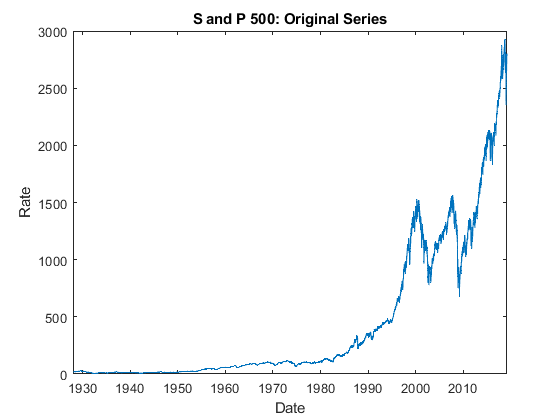

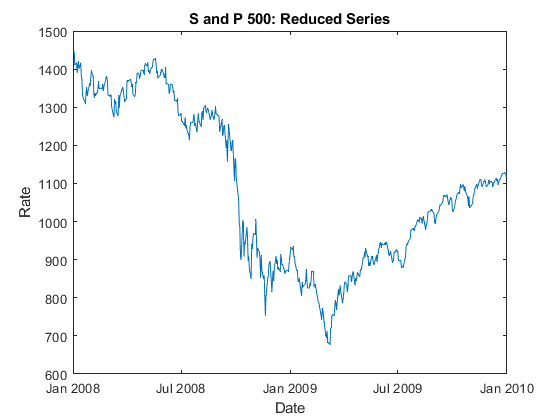

S_And_P500_RawData = InFileToTimeTable(S_and_P_500_TSFileName, TSFilePath, TSFileExt, blnShowOrigPlots,blnShowNormalisedPlots,blnUseDateRange,DateFrom,DateTo,PltXAxis,PltYAxis);


if blnUseDateRange == 1
      Range = timerange(DateFrom,DateTo);
      S_And_P500_Reduced_RawData = S_And_P500_RawData(Range,:);
      TS_Series = S_And_P500_Reduced_RawData.Rate(:,1);
else  
      TS_Series = S_And_P500_RawData.Rate(:,1);             %running full series for now
      S_And_P500_Reduced_RawData = S_And_P500_RawData;      %No need to reduce data to range if looking at full series. This makes sure Examined series values returned in structure are correct
end

## Create SAX String from Matlab Code

data = TS_Series;                   %For Passing Series into SAX function call
[data_len, na] = size(data);        %Get Length of Series for SAX function call
nseg = data_len;                    %Used to control compression levels (on x-axis) i.e how much of original series does each SAX symbol represent
                                    %if nseg = data_len then no compression otherwise length of series (data_len) must be divisible by number of segments (nseg)                                 
alphabet_size = 20;                 %Set size of alphabet i.e. number of distinct symbols used to rtepresent original series

**Note:** setting *nseg = data_len;* means we are not using any copmpression in our SAX representaions here. 

            We willl therefore have a 1:1 match between SAX and raw series elements.

            The code needs to be generalised to allow for 

%Generate SAX string from Keogh Code
[SAXResult, SAXPointer] = timeseries2symbol(data, data_len, nseg, alphabet_size);

% %For MP analysis of SAX string with exising MP code create SAX Result table that includes a date for each symbol.
% %This is currently a 1:1 match as we are not doing any copmpression (on x-axis) i.e how much of original series does each SAX symbol represent, we are setting nseg = data_len; 
SAXResultRawData = S_And_P500_Reduced_RawData;% Create copy of ReducedData table
SAXResultRawData = addvars(SAXResultRawData,transpose(SAXResult)); % Add Column with SAX string values
SAXResultRawData = removevars(SAXResultRawData,"Rate"); % Remove rate column
SAXResultRawData = renamevars(SAXResultRawData,"Var2","Rate"); % Rename SAX column to Rate (Need to use same columnnames as other MP programs)

## Create SAX String From Input File

------------------------------------------------------------------------------------------------------------------------------------

**Note: *****S_and_P_500_SAX_Str_FileName*** is created by a seperate Python Program in order to allow us to use output from the the TSLearn library

The output of this python program is a series of .csv files containging SAX values of the S&P500 over a range of Alphabet sizes.

The individual file used here in this script called "S_and_P_500_SAX_Series" consists of a SAX representation of the S&P500 created by the TSLearn library with an alphabet size of **XXXXX**

------------------------------------------------------------------------------------------------------------------------------------

S_and_P_500_SAX_Str_FileName  = "S_and_P_500_SAX_Series";
SAXSeriesFileExt   = ".csv";

%Create full filename including path for import
SAXFileName = TSFilePath + S_and_P_500_SAX_Str_FileName + SAXSeriesFileExt; 

fid = fopen(SAXFileName);
a = textscan(fid,'%s',1);
fclose(fid);

%read into initial table and convert into timetable
opts = detectImportOptions(SAXFileName);
opt =  delimitedTextImportOptions;
S_And_P500_RawData = readtable(SAXFileName,'ReadRowNames',false); 
S_And_P500_RawData = table2timetable(S_And_P500_RawData);
FileSAXResultRawData = S_And_P500_RawData;

## Assign SAX String Representations

TS_Keogh_SAX_Series = SAXResult; %i.e SAX series created by Matlab code above
TS_TSLearn_SAX_Series = FileSAXResultRawData.Rate(:,1);
TS_TSLearn_SAX_Series = transpose(TS_TSLearn_SAX_Series); %Transpose to put in same format as other series so treated in same way for remainder of script 

------------------------------------------------------------------------------------------------------------------------------------

**Note: **For experimentation we have now created 2 seperate SAX series based off the S&P500 input series

The first using Matlab code named '***TS_Keogh_SAX_Series***' 

The second using a seperate python script. named '***TS_TSLearn_SAX_Series***'

This is required as the matlab code has a max alphabet size of 20 currently available and we may require higher alphabet size SAX strings for analysis in order to obtain a suitable compression rate.

------------------------------------------------------------------------------------------------------------------------------------

## Display SAX Representations & Raw Series With Dates

disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


disp('      For comparison raw S&P series along with both SAX series are shown')

      For comparison raw S&P series along with both SAX series are shown


disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


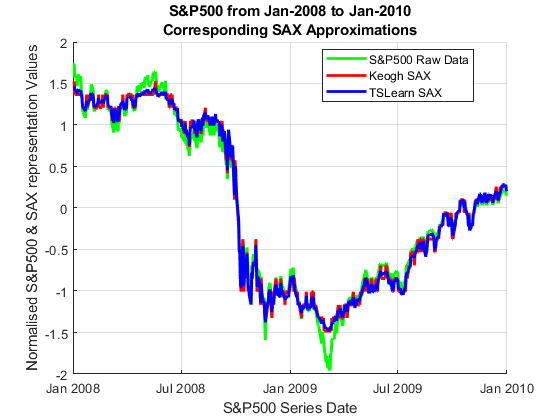


strKeoghSeriesLegend = "Keogh SAX";
strTSLearnSAXSeriesLegend = "TSLearn SAX";
strRawSeriesLegend = "S&P500 Raw Data";
strXLabel = "S&P500 Series Date";
strYLabel = "Normalised S&P500 & SAX representation Values";
%strTitle = "Keogh vs TSLearn SAX Approximation of S&P500";
strTitle = "S&P500 from " + datestr(DateFrom,'mmm-yyyy') + " to " + datestr(DateTo,'mmm-yyyy') + newline + "Corresponding SAX Approximations";

%Just make sure we're usingh the correct S&P500 data
TS_Series_Dates = S_And_P500_Reduced_RawData.Date;
TS_Series_Values = S_And_P500_Reduced_RawData.Rate;
    
%In this case we know num of SAX elements = Num of S&P500 elements so can use same dates for all series
%i.e. we have a 1:1 match between SAX & raw series values

Keogh_Vs_TSLearn_SAX_With_Dates=figure();
hold on
    plot(TS_Series_Dates,normalize(TS_Series_Values),'color','green','DisplayName',strRawSeriesLegend,'LineWidth',2);
    plot(TS_Series_Dates, normalize(TS_Keogh_SAX_Series),'color','red','DisplayName',strKeoghSeriesLegend,'LineWidth',2);
    plot(TS_Series_Dates,normalize(TS_TSLearn_SAX_Series),'color','blue','DisplayName',strTSLearnSAXSeriesLegend,'LineWidth',2);

    %Show legend & Grid
    grid on;
    legend({strRawSeriesLegend,strKeoghSeriesLegend,strTSLearnSAXSeriesLegend})     
    legend('Location','best','color','white');      

    title(strTitle)
    xlabel(strXLabel)
    ylabel(strYLabel)
hold off

## Setup Matrix Profile run for SAX String & Raw Data

## i.e Associate SAX values with dates

%For MP analysis of SAX string with exising MP code create SAX Result table that includes a date for each symbol.
%This is currently a 1:1 match as we are not doing any copmpression (on x-axis) i.e how much of original series does each SAX symbol represent, we are setting nseg = data_len above; 

%Do For Keogh SAX Series First
TS_Keogh_Series_SAX_RawData = S_And_P500_Reduced_RawData;% Create copy of ReducedData table
TS_Keogh_Series_SAX_RawData = addvars(TS_Keogh_Series_SAX_RawData,transpose(TS_Keogh_SAX_Series)); % Add Column with SAX string values from TS_Keogh_Series above
TS_Keogh_Series_SAX_RawData = removevars(TS_Keogh_Series_SAX_RawData,"Rate"); % Remove rate column
TS_Keogh_Series_SAX_RawData = renamevars(TS_Keogh_Series_SAX_RawData,"Var2","Rate"); % Rename SAX column to Rate (Need to use same columnnames as other MP programs)

% %Do For Keogh SAX Series First
TS_TSLearn_Series_SAX_RawData = S_And_P500_Reduced_RawData;% Create copy of ReducedData table
TS_TSLearn_Series_SAX_RawData = addvars(TS_TSLearn_Series_SAX_RawData,transpose(TS_TSLearn_SAX_Series)); % Add Column with SAX string values from TS_TSLearn_Series above
TS_TSLearn_Series_SAX_RawData = removevars(TS_TSLearn_Series_SAX_RawData,"Rate"); % Remove rate column
TS_TSLearn_Series_SAX_RawData = renamevars(TS_TSLearn_Series_SAX_RawData,"Var2","Rate"); % Rename SAX column to Rate (Need to use same columnnames as other MP programs)

## Create Matrix Profiles for SAX Strings & Raw Data

RawSeriesMatrixProfileResults = RunMatrixProfiles(S_And_P500_Reduced_RawData, blnUseMotifRange, SetMotifLength, MinMotifLength, MaxMotifLength, blnUseMotifLengthStepSize, MotifLengthStepSize, blnUseDateRange, DateFrom, DateTo);
TS_Keogh_Series_SAXMatrixProfileResults = RunMatrixProfiles(TS_Keogh_Series_SAX_RawData, blnUseMotifRange, SetMotifLength, MinMotifLength, MaxMotifLength, blnUseMotifLengthStepSize, MotifLengthStepSize, blnUseDateRange, DateFrom, DateTo);
TS_TSLearn_Series_SAXMatrixProfileResults = RunMatrixProfiles(TS_TSLearn_Series_SAX_RawData, blnUseMotifRange, SetMotifLength, MinMotifLength, MaxMotifLength, blnUseMotifLengthStepSize, MotifLengthStepSize, blnUseDateRange, DateFrom, DateTo);

## Get Dates And Values From Matrix Profiles For Plotting Comparisons

%We are restricting the time range to the same Date From & To as set above
TR = timerange(DateFrom,DateTo);
NumProfilesRan = size(RawSeriesMatrixProfileResults(),2);

%Raw Series MP Dates & Values
Raw_Series_Matrix_Profile = RawSeriesMatrixProfileResults(1).MatrixProfile;               
Raw_Series_Matrix_Profile_Series_Length = size(Raw_Series_Matrix_Profile);                      
Raw_Series_Matrix_Profile_Dates = RawSeriesMatrixProfileResults(1).Full_Series.Date(TR,:); %Get list of dates in time window from raw data series
Raw_Series_Matrix_Profile_Dates_Tailored =Raw_Series_Matrix_Profile_Dates(1:Raw_Series_Matrix_Profile_Series_Length);% Trim to Matrix Profile length 

%Keogh SAX Series MP Dates & Values
TS_Keogh_Series_SAX_Matrix_Profile = TS_Keogh_Series_SAXMatrixProfileResults(1).MatrixProfile;               
TS_Keogh_Series_SAX_Matrix_Profile_Series_Length = size(TS_Keogh_Series_SAX_Matrix_Profile);                      
TS_Keogh_Series_SAX_Matrix_Profile_Dates = TS_Keogh_Series_SAXMatrixProfileResults(1).Full_Series.Date(TR,:); %Get list of dates in time window from raw data series
TS_Keogh_Series_SAX_Matrix_Profile_Dates_Tailored =TS_Keogh_Series_SAX_Matrix_Profile_Dates(1:TS_Keogh_Series_SAX_Matrix_Profile_Series_Length);% Trim to Matrix Profile length 

%TS_TSLearn SAX Series MP Dates & Values
TS_TSLearn_Series_SAX_Matrix_Profile = TS_TSLearn_Series_SAXMatrixProfileResults(1).MatrixProfile;               
TS_TSLearn_Series_SAX_Matrix_Profile_Series_Length = size(TS_TSLearn_Series_SAX_Matrix_Profile);                      
TS_TSLearn_Series_SAX_Matrix_Profile_Dates = TS_TSLearn_Series_SAXMatrixProfileResults(1).Full_Series.Date(TR,:); %Get list of dates in time window from raw data series
TS_TSLearn_Series_SAX_Matrix_Profile_Dates_Tailored =TS_TSLearn_Series_SAX_Matrix_Profile_Dates(1:TS_TSLearn_Series_SAX_Matrix_Profile_Series_Length);% Trim to Matrix Profile length 

## Get MDL SAX Details From SAX Series

------------------------------------------------------------------------------------------------------------------------------------

**Note: **This is the point where we apply MDL principle to the SAX series.

           Application is handled in a seperate function called ***SAX_To_MDL*** that takes the SAX series and raw series as input.

          Output is a table containing MDL-SAX details for further analysis.

------------------------------------------------------------------------------------------------------------------------------------

%Get MDL SAX Table from SAX Series
TS_Keogh_Series_MDLSAX= SAX_To_MDL(TS_Keogh_SAX_Series, TS_Keogh_Series_SAX_RawData);       %Creating MDL_SAX Table (Need same raw data used for creating SAX string here also for getting dates of indexes in original series where comprression occurs
TS_TSLearn_Series_MDLSAX= SAX_To_MDL(TS_TSLearn_SAX_Series, TS_TSLearn_Series_SAX_RawData); %Creating MDL_SAX Table (Need same raw data used for creating SAX string here also for getting dates of indexes in original series where comprression occurs

------------------------------------------------------------------------------------------------------------------------------------

**Note: **Now setting up and running matrix profiles against the MDL-Sax series

------------------------------------------------------------------------------------------------------------------------------------

## Setup Matrix Profile run for MDL SAX Series

%For MP analysis of MDL SAX string with exising MP code create SAX Result table that includes a date for each symbol.

%Do For Keogh SAX Series First
TS_Keogh_Series_MDLSAX_RawData =timetable;
TS_Keogh_Series_MDLSAX_RawData = table2timetable(TS_Keogh_Series_MDLSAX(:,{'RawSeriesDate','SAXVal'}));
%TS_Keogh_Series_MDLSAX_RawData = renamevars(TS_Keogh_Series_MDLSAX_RawData,"RawSeriesDate","Date"); % Rename RawSeriesDate column to Date (Need to use same columnnames as other MP programs)
TS_Keogh_Series_MDLSAX_RawData = renamevars(TS_Keogh_Series_MDLSAX_RawData,"SAXVal","Rate"); % Rename SAX column to Rate (Need to use same columnnames as other MP programs)

%Then TS Learn Series
TS_TSLearn_Series_MDLSAX_RawData =timetable;
TS_TSLearn_Series_MDLSAX_RawData = table2timetable(TS_TSLearn_Series_MDLSAX(:,{'RawSeriesDate','SAXVal'}));
%TS_TSLearn_Series_MDLSAX_RawData = renamevars(TS_TSLearn_Series_MDLSAX_RawData,"RawSeriesDate","Date"); % Rename RawSeriesDate column to Date (Need to use same columnnames as other MP programs)
TS_TSLearn_Series_MDLSAX_RawData = renamevars(TS_TSLearn_Series_MDLSAX_RawData,"SAXVal","Rate"); % Rename SAX column to Rate (Need to use same columnnames as other MP programs)

## Create Matrix Profiles for MDL SAX Series

TS_Keogh_Series_MDLSAX_MatrixProfileResults = RunMatrixProfiles(TS_Keogh_Series_MDLSAX_RawData, blnUseMotifRange, SetMotifLength, MinMotifLength, MaxMotifLength, blnUseMotifLengthStepSize, MotifLengthStepSize, blnUseDateRange, DateFrom, DateTo);
TS_TSLearn_Series_MDLSAX_MatrixProfileResults = RunMatrixProfiles(TS_TSLearn_Series_MDLSAX_RawData, blnUseMotifRange, SetMotifLength, MinMotifLength, MaxMotifLength, blnUseMotifLengthStepSize, MotifLengthStepSize, blnUseDateRange, DateFrom, DateTo);

## Get Dates And Values From MDL SAX Matrix Profiles For Plotting Comparisons

%We are restricting the tine range to the same Date From & To as set above
TR = timerange(DateFrom,DateTo);

%Keogh SAX Series MP Dates & Values
TS_Keogh_Series_MDLSAX_Matrix_Profile = TS_Keogh_Series_MDLSAX_MatrixProfileResults(1).MatrixProfile;               
TS_Keogh_Series_MDLSAX_Matrix_Profile_Series_Length = size(TS_Keogh_Series_MDLSAX_Matrix_Profile);                      
TS_Keogh_Series_MDLSAX_Matrix_Profile_Dates = TS_Keogh_Series_MDLSAX_MatrixProfileResults(1).Full_Series.RawSeriesDate(TR,:); %Get list of dates in time window from raw data series
TS_Keogh_Series_MDLSAX_Matrix_Profile_Dates_Tailored =TS_Keogh_Series_MDLSAX_Matrix_Profile_Dates(1:TS_Keogh_Series_MDLSAX_Matrix_Profile_Series_Length);% Trim to Matrix Profile length 

%TS_TSLearn SAX Series MP Dates & Values
TS_TSLearn_Series_MDLSAX_Matrix_Profile = TS_TSLearn_Series_MDLSAX_MatrixProfileResults(1).MatrixProfile;               
TS_TSLearn_Series_MDLSAX_Matrix_Profile_Series_Length = size(TS_TSLearn_Series_MDLSAX_Matrix_Profile);                      
TS_TSLearn_Series_MDLSAX_Matrix_Profile_Dates = TS_TSLearn_Series_MDLSAX_MatrixProfileResults(1).Full_Series.RawSeriesDate(TR,:); %Get list of dates in time window from raw data series
TS_TSLearn_Series_MDLSAX_Matrix_Profile_Dates_Tailored =TS_TSLearn_Series_MDLSAX_Matrix_Profile_Dates(1:TS_TSLearn_Series_MDLSAX_Matrix_Profile_Series_Length);% Trim to Matrix Profile length 

------------------------------------------------------------------------------------------------------------------------------------

**Note: **Now looking at low MP values from the Matlab MDL-SAX String i..e point sof closest match.

          This is a manual process it needs to be automated at a later date.

------------------------------------------------------------------------------------------------------------------------------------

## Display Just  MDL SAX Matrix Profile For Low MP Value Analysis

strKeoghSeriesLegend = "MDL-SAX MP";
strXLabel = "Matrix Profile Date";
strYLabel = "Matrix Profile Distance Value";
strTitle = "S&P500 from " + datestr(DateFrom,'mmm-yyyy') + " to " + datestr(DateTo,'mmm-yyyy') + newline + "Corresponding MDL-SAX Matrix Profile" + newline + " SAX Alphabet size: " + string(alphabet_size) + ", MP Length: " + string(SetMotifLength);
disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


disp('      MDL-SAX MP plot with dates (for paper)')

      MDL-SAX MP plot with dates (for paper)


disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


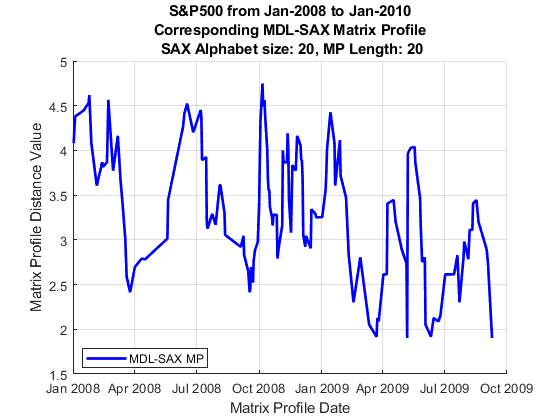

Just_MDLSAX_Matrix_Profile_For_Low_MP_Value_Analysis_Dates_Plot=figure();
hold on
    plot(datetime(TS_Keogh_Series_MDLSAX_Matrix_Profile_Dates_Tailored),TS_Keogh_Series_MDLSAX_Matrix_Profile,'LineWidth',2,'Color','blue',"LineStyle","-");

    %Show legend & Grid
    grid on;
    legend({strKeoghSeriesLegend})     
    legend('Location','best','color','white');      

    title(strTitle)
    xlabel(strXLabel)
    ylabel(strYLabel)
hold off


disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


disp('      MDL-SAX MP plot with indexes (used to pick out low MP values from from MDL-SAX MP plot)')

      MDL-SAX MP plot with indexes (used to pick out low MP values from from MDL-SAX MP plot)


disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


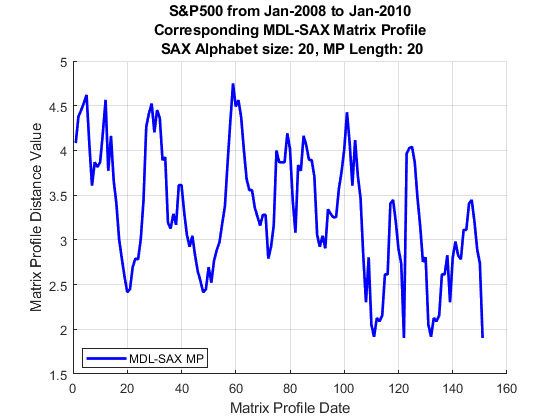

Just_MDLSAX_Matrix_Profile_For_Low_MP_Value_Indexes_Plot=figure();
hold on
    plot(TS_Keogh_Series_MDLSAX_Matrix_Profile,'LineWidth',2,'Color','blue',"LineStyle","-");

    %Show legend & Grid
    grid on;
    legend({strKeoghSeriesLegend})     
    legend('Location','best','color','white');      

    title(strTitle)
    xlabel(strXLabel)
    ylabel(strYLabel)
hold off


disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


disp('      Indexes of low MP values visually identified from MDL-SAX MP plot')

      Indexes of low MP values visually identified from MDL-SAX MP plot


disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


%Low value 1
intMin1 = 20;
strMatch1 = "Low Matrix profile value 1: Index: " + intMin1 + " points to Index: " + TS_Keogh_Series_MDLSAX_MatrixProfileResults.ProfileIndex(intMin1) + " of Keogh MDL-SAX Matrix Profile";
disp(strMatch1);

Low Matrix profile value 1: Index: 20 points to Index: 48 of Keogh MDL-SAX Matrix Profile



%Low value 2
intMin2 = 48;
strMatch2 = "Low Matrix profile value 2: Index: " + intMin2 + " points to Index: " + TS_Keogh_Series_MDLSAX_MatrixProfileResults.ProfileIndex(intMin2) + " of Keogh MDL-SAX Matrix Profile";
disp(strMatch2);

Low Matrix profile value 2: Index: 48 points to Index: 20 of Keogh MDL-SAX Matrix Profile



%Low value 3
intMin3 = 111;
strMatch3 = "Low Matrix profile value 3: Index: " + intMin3 + " points to Index: " + TS_Keogh_Series_MDLSAX_MatrixProfileResults.ProfileIndex(intMin3) + " of Keogh MDL-SAX Matrix Profile";
disp(strMatch3);

Low Matrix profile value 3: Index: 111 points to Index: 132 of Keogh MDL-SAX Matrix Profile



%Low value 4
intMin4 = 122;
strMatch4 = "Low Matrix profile value 4: Index: " + intMin4 + " points to Index: " + TS_Keogh_Series_MDLSAX_MatrixProfileResults.ProfileIndex(intMin4) + " of Keogh MDL-SAX Matrix Profile";
disp(strMatch4);

Low Matrix profile value 4: Index: 122 points to Index: 151 of Keogh MDL-SAX Matrix Profile



%Low value 5
intMin5 = 132;
strMatch5 = "Low Matrix profile value 4: Index: " + intMin5 + " points to Index: " + TS_Keogh_Series_MDLSAX_MatrixProfileResults.ProfileIndex(intMin5) + " of Keogh MDL-SAX Matrix Profile";
disp(strMatch5);

Low Matrix profile value 4: Index: 132 points to Index: 111 of Keogh MDL-SAX Matrix Profile


## SAX & Raw Series plots based off Low MDL SAX Matrix Profile Values

------------------------------------------------------------------------------------------------------------------------------------

**Note: **We now waat to plot the SAX String and Raw series subsequences as highlighted by these low MP values (coming from the MDL SAX String).

          This is handled iin a function called GetRawSeriesDataFromMDLSAX, we pass the relevant MDL-SAX MP index in along with a series of flags controlling 

          which plots and raw data we may want to display along with raw data , MP & SAX values etc.

        Only 9D plot is shown here but the others can easily be uncommented below.

------------------------------------------------------------------------------------------------------------------------------------

blnShowMDLTableVals= 0;           %Used to set if we want to display the values from the MDL SAX table that the SAX series plot is based on
blnShowSAXSeriesPlot = 0;         %Used to set if we want to display the SAX series plot of the segments identified based on the input index (intMin1)
blnShowSAXSeriesPlotNoMDL =0;
blnShowRawSeriesTableVals = 0;    %Used to set if we want to display the table values from the Raw Time Series table (i.e. S_And_P500_Reduced_RawData) that the raw series plot is based on
blnShowRawDataSeriesPlot = 0;     %Used to set if we want to display the raw data series plot of the segments identified based on the input index (intMin1)
blnShowTiledPlots = 1;            %Used to set if we want to display SAX,MDL-SAX & Raw Series plots in a single tiled figure ;


%Call for plot used in Fig9B
% disp('---------------------------------------------------------------------------------')
% disp('      Plot used in Fig9B')
% disp('---------------------------------------------------------------------------------')
%[Fig6Bside1RawSeriesData, Fig6Bside2RawSeriesData,Fig6Bside1_MDLSAX_RawSeriesLegend, Fig6Bside2_MDLSAX_RawSeriesLegend] = GetRawSeriesDataFromMDLSAX(intMin1,blnShowMDLTableVals,blnShowRawSeriesTableVals,blnShowSAXSeriesPlot,blnShowSAXSeriesPlotNoMDL,blnShowRawDataSeriesPlot,blnShowTiledPlots,TS_Keogh_Series_MDLSAX_MatrixProfileResults,TS_Keogh_Series_MDLSAX,S_And_P500_Reduced_RawData,TS_Keogh_SAX_Series,"S&P500");

%IntMin2 wasn't used as it is the same result as intMin1
%[side1RawSeriesData, side2RawSeriesData,side1MDL_SAX_RawSeriesLegend, side2MDL_SAX_RawSeriesLegend] = GetRawSeriesDataFromMDLSAX(intMin2,blnShowMDLTableVals,blnShowRawSeriesTableVals,blnShowSAXSeriesPlot,blnShowSAXSeriesPlotNoMDL,blnShowRawDataSeriesPlot,blnShowTiledPlots,TS_Keogh_Series_MDLSAX_MatrixProfileResults,TS_Keogh_Series_MDLSAX,S_And_P500_Reduced_RawData,TS_Keogh_SAX_Series,"S&P500");

%Call for plot used in Fig9C
% disp('---------------------------------------------------------------------------------')
% disp('      Plot used in Fig9C')
% disp('---------------------------------------------------------------------------------')
%[Fig6Cside1RawSeriesData, Fig6Cside2RawSeriesData,Fig6Cside1_MDLSAX_RawSeriesLegend, Fig6Cside2_MDLSAX_RawSeriesLegend] = GetRawSeriesDataFromMDLSAX(intMin3,blnShowMDLTableVals,blnShowRawSeriesTableVals,blnShowSAXSeriesPlot,blnShowSAXSeriesPlotNoMDL,blnShowRawDataSeriesPlot,blnShowTiledPlots,TS_Keogh_Series_MDLSAX_MatrixProfileResults,TS_Keogh_Series_MDLSAX,S_And_P500_Reduced_RawData,TS_Keogh_SAX_Series,"S&P500");

%Call for plot used in Fig9D
disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


disp('      Plot used in Fig9D')

      Plot used in Fig9D


disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------



Warning..... setting end index of Side 2 to 170 from 171 due to max size of MDLSAX table (170)


Side 1&2 MDL-SAX segment length: 21
Side 1 SAX segment (No MDL) length: 61
Side 2 SAX segment (No MDL) length: 79


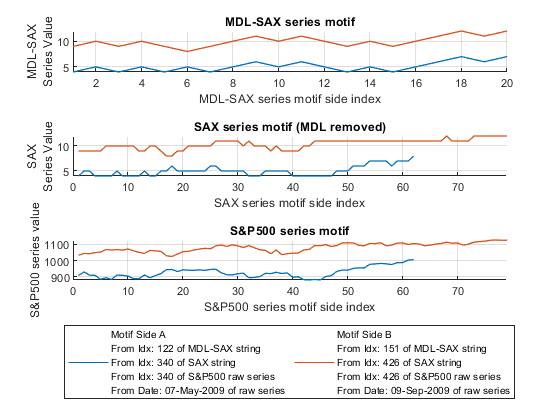

[Fig6Dside1RawSeriesData, Fig6Dside2RawSeriesData,Fig6Dside1_MDLSAX_RawSeriesLegend, Fig6Dside2_MDLSAX_RawSeriesLegend] = GetRawSeriesDataFromMDLSAX(intMin4,blnShowMDLTableVals,blnShowRawSeriesTableVals,blnShowSAXSeriesPlot,blnShowSAXSeriesPlotNoMDL,blnShowRawDataSeriesPlot,blnShowTiledPlots,TS_Keogh_Series_MDLSAX_MatrixProfileResults,TS_Keogh_Series_MDLSAX,S_And_P500_Reduced_RawData,TS_Keogh_SAX_Series,"S&P500");


%intMin5 also not used here
%[side1RawSeriesData, side2RawSeriesData,side1MDL_SAX_RawSeriesLegend, side2MDL_SAX_RawSeriesLegend] = GetRawSeriesDataFromMDLSAX(intMin5,blnShowMDLTableVals,blnShowRawSeriesTableVals,blnShowSAXSeriesPlot,blnShowSAXSeriesPlotNoMDL,blnShowRawDataSeriesPlot,blnShowTiledPlots,TS_Keogh_Series_MDLSAX_MatrixProfileResults,TS_Keogh_Series_MDLSAX,S_And_P500_Reduced_RawData,TS_Keogh_SAX_Series,"S&P500");

------------------------------------------------------------------------------------------------------------------------------------

**Note: **Now comparing motifs found using SLIM approach above to raw S&P500 series MP motifs

          This is handled in the function ***PlotMotifsFromMatrixProfileResultsStructure***

------------------------------------------------------------------------------------------------------------------------------------

%------------------------
%--Plot B Details
%------------------------
%Motif Side A
%From Idx: 20 of MDL-SAX string
%From Idx: 57 of SAX string
%From Idx: 57 of S&P500 raw series
%From Date: 25-Mar-2008 of raw series
%Motif Side B
%From Idx: 48 of MDL-SAX string
%From Idx: 180 of SAX string
%From Idx: 180 of S&P500 raw series
%From Date: 17-Sep-2008 of raw series

%Raw_Series_Matrix_Profile
%PlotMotifsFromMatrixProfileResultsStructure(RawSeriesMatrixProfileResults,20,0)
%PlotMotifsFromMatrixProfileResultsStructure(RawSeriesMatrixProfileResults,20,1)

%Raw Series Matrix Profile & MDL-SAX 
% PlotMotifsFromMatrixProfileResultsStructureIncludingMDLSAXMotif(RawSeriesMatrixProfileResults,57,0,Fig6Bside1RawSeriesData, Fig6Bside2RawSeriesData,1,1,"S&P500","Fig6B:",Fig6Bside1_MDLSAX_RawSeriesLegend, Fig6Bside2_MDLSAX_RawSeriesLegend)
% PlotMotifsFromMatrixProfileResultsStructureIncludingMDLSAXMotif(RawSeriesMatrixProfileResults,57,1,Fig6Bside1RawSeriesData, Fig6Bside2RawSeriesData,1,1,"S&P500","Fig6B:",Fig6Bside1_MDLSAX_RawSeriesLegend, Fig6Bside2_MDLSAX_RawSeriesLegend)


%------------------------
%--Plot C Details
%------------------------
%Motif Side A
%From Idx: 111 of MDL-SAX string
%From Idx: 308 of SAX string
%From Idx: 308 of S&P500 raw series
%From Date: 23-Mar-2009 of raw series
%Motif Side B
%From Idx: 132 of MDL-SAX string
%From Idx: 364 of SAX string
%From Idx: 364 of S&P500 raw series
%From Date: 11-Jun-2009 of raw series

%Raw_Series_Matrix_Profile
%PlotMotifsFromMatrixProfileResultsStructure(RawSeriesMatrixProfileResults,308,0)
%PlotMotifsFromMatrixProfileResultsStructure(RawSeriesMatrixProfileResults,308,1)

%Raw Series Matrix Profile & MDL-SAX 
% PlotMotifsFromMatrixProfileResultsStructureIncludingMDLSAXMotif(RawSeriesMatrixProfileResults,308,0,Fig6Cside1RawSeriesData, Fig6Cside2RawSeriesData,1,1,"S&P500","Fig6C:",Fig6Cside1_MDLSAX_RawSeriesLegend, Fig6Cside2_MDLSAX_RawSeriesLegend)
% PlotMotifsFromMatrixProfileResultsStructureIncludingMDLSAXMotif(RawSeriesMatrixProfileResults,308,1,Fig6Cside1RawSeriesData, Fig6Cside2RawSeriesData,1,1,"S&P500","Fig6C:",Fig6Cside1_MDLSAX_RawSeriesLegend, Fig6Cside2_MDLSAX_RawSeriesLegend)

%------------------------
%--Plot D Details
%------------------------
% Motif Side A
% From Idx: 122 of MDL-SAX string
% From Idx: 340 of SAX string
% From Idx: 340 of S&P500 raw series
% From Date: 07-May-2009 of raw series
% Motif Side B
% From Idx: 151 of MDL-SAX string
% From Idx: 426 of SAX string
% From Idx: 426 of S&P500 raw series
% From Date: 09-Sep-2009 of raw series

%Raw_Series_Matrix_Profile
%PlotMotifsFromMatrixProfileResultsStructure(RawSeriesMatrixProfileResults,340,0)
%PlotMotifsFromMatrixProfileResultsStructure(RawSeriesMatrixProfileResults,340,1)

%Raw Series Matrix Profile & MDL-SAX 
%Not normalised raw series call
%PlotMotifsFromMatrixProfileResultsStructureIncludingMDLSAXMotif(RawSeriesMatrixProfileResults,340,0,Fig6Dside1RawSeriesData, Fig6Dside2RawSeriesData,1,1,"S&P500","Fig6D:",Fig6Dside1_MDLSAX_RawSeriesLegend, Fig6Dside2_MDLSAX_RawSeriesLegend)
%Normalised raw series call (including combined into single plot)
%PlotMotifsFromMatrixProfileResultsStructureIncludingMDLSAXMotif(RawSeriesMatrixProfileResults,340,1,Fig6Dside1RawSeriesData, Fig6Dside2RawSeriesData,1,1,"S&P500","Fig6D:",Fig6Dside1_MDLSAX_RawSeriesLegend, Fig6Dside2_MDLSAX_RawSeriesLegend)


disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


disp('      Comparison to raw series MP plot used in Fig10B')

      Comparison to raw series MP plot used in Fig10B


disp('---------------------------------------------------------------------------------')

---------------------------------------------------------------------------------


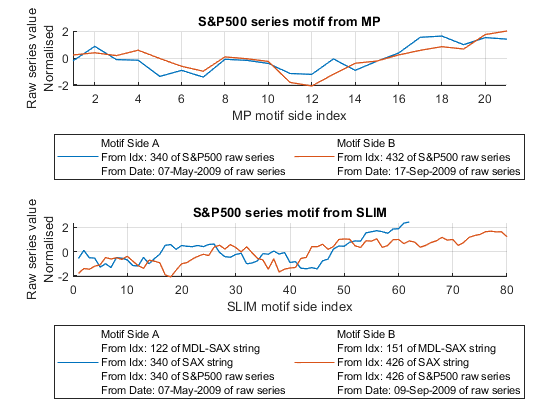

%Normalised raw series call (showing just tiled plot)
PlotMotifsFromMatrixProfileResultsStructureIncludingMDLSAXMotif(RawSeriesMatrixProfileResults,340,1,Fig6Dside1RawSeriesData, Fig6Dside2RawSeriesData,0,1,"S&P500","Fig6D:",Fig6Dside1_MDLSAX_RawSeriesLegend, Fig6Dside2_MDLSAX_RawSeriesLegend)

## Plot Motifs From Matrix Profile Results Structure With MDLSAX Motifs Function

function PlotMotifsFromMatrixProfileResultsStructureIncludingMDLSAXMotif(MatrixProfileResults,MotifIndex,blnShowMotifsNormalized,MDLSAXMotifSide1Data,MDLSAXMotifSide2Data,blnshowCombinedPlot,blnshowTiledPlot,inStrRawSeriesName,instrPlotTitle,instrSide1_MDLSAX_RawSeriesLegend,instrSide2_MDLSAX_RawSeriesLegend)
    %--------------------------------
    % Gather MP Motifs Data
    %--------------------------------
    MP_Motif_A_StartIdx = MotifIndex; 
    MP_Motif_B_StartIdx = MatrixProfileResults.ProfileIndex(MP_Motif_A_StartIdx);
    
    MP_Motif_A_StartDate = MatrixProfileResults.Examined_Series.Date(MP_Motif_A_StartIdx);
    MP_Motif_B_StartDate = MatrixProfileResults.Examined_Series.Date(MP_Motif_B_StartIdx);
    
    MP_MotifLength = MatrixProfileResults.MotifLength;
        
    MP_Motif_A_Data = MatrixProfileResults.Examined_Series.Rate(MP_Motif_A_StartIdx:MP_Motif_A_StartIdx+ MP_MotifLength,1);
    MP_Motif_B_Data = MatrixProfileResults.Examined_Series.Rate(MP_Motif_B_StartIdx:MP_Motif_B_StartIdx+ MP_MotifLength,1);
    
    %Get X-Axis limit of MP motif to tidy up plots below
    [intMP_Motif_XAxisLimit,NA]= size(MP_Motif_B_Data);
    
    %--------------------------------
    % Gather MDLSAX Motifs Data
    %--------------------------------
    MDLSAX_Motif_A_Data = MDLSAXMotifSide1Data.Rate;
    MDLSAX_Motif_B_Data = MDLSAXMotifSide2Data.Rate;
    
    %Get X-Axis limit of MDLSAX_Motif motif to tidy up plots below
    [intMDLSAX_Side1_Motif_XAxisLimit,NA]= size(MDLSAX_Motif_A_Data);%Getting Side 1 Motif Length
    [intMDLSAX_Side2_Motif_XAxisLimit,NA]= size(MDLSAX_Motif_B_Data);%Getting Side 2 Motif Length
    %Set value of X Axis limit to larger of the two
    if intMDLSAX_Side1_Motif_XAxisLimit > intMDLSAX_Side2_Motif_XAxisLimit
        intMDLSAX_Motif_XAxisLimit = intMDLSAX_Side1_Motif_XAxisLimit;
    else
        intMDLSAX_Motif_XAxisLimit = intMDLSAX_Side2_Motif_XAxisLimit;
    end
    
    if blnShowMotifsNormalized == 1
        MP_Motif_A_Data = normalize(MP_Motif_A_Data);
        MP_Motif_B_Data = normalize(MP_Motif_B_Data);
        
        MDLSAX_Motif_A_Data = normalize(MDLSAX_Motif_A_Data);
        MDLSAX_Motif_B_Data = normalize(MDLSAX_Motif_B_Data);
    end
    
    %Only show combined MP & MDLSAX(SLIM) motifs plot if asked
    if blnshowCombinedPlot == 1
        MDLSAX_NoMDLSAX_Raw_Series_Combined_Plot=figure();
        hold on
        
                strTitle = inStrRawSeriesName + " series motifs from MP and SLIM";
                strXlabel = "Motif side index";
                if blnShowMotifsNormalized == 1 %Vary Y axis label depending on normalised plot or not
                    strYlabel = "Raw series value" + newline + "Normalised";
                else
                    strYlabel = "Raw series value";
                end
                
                strMPSide1Legend = "MP Motif Side A" + newline + "From Idx: " + MP_Motif_A_StartIdx + " of " + inStrRawSeriesName + " raw series" + newline + "From Date: " + datestr(MP_Motif_A_StartDate) + " of raw series";
                strMPSide2Legend = "MP Motif Side B" + newline + "From Idx: " + MP_Motif_B_StartIdx + " of " + inStrRawSeriesName + " raw series" + newline + "From Date: " + datestr(MP_Motif_B_StartDate) + " of raw series"; 
                strMDLSAXSide1Legend = instrSide1_MDLSAX_RawSeriesLegend;
                strMDLSAXSide2Legend = instrSide2_MDLSAX_RawSeriesLegend;
                
                plot(MP_Motif_A_Data,'LineWidth',1);
                plot(MP_Motif_B_Data,'LineWidth',1);
                
                plot(MDLSAX_Motif_A_Data,'LineWidth',1);
                plot(MDLSAX_Motif_B_Data,'LineWidth',1);
                
                
                title(strTitle)
                xlabel(strXlabel) 
                ylabel(strYlabel) 
                grid on;    

                
                lh =legend({strMPSide1Legend, strMPSide2Legend, strMDLSAXSide1Legend,strMDLSAXSide2Legend},'Location','eastoutside','Orientation','vertical');
                legend show;
                
                %Set Max size of x-Axis to longest motif length (i.e from SLIM motifs)
                xlim([1 intMDLSAX_Motif_XAxisLimit])
        hold off
    end
    
    
    %Only show tiled MP & MDLSAX(SLIM) motifs plot if asked
    if blnshowTiledPlot == 1
        
        MDLSAX_NoMDLSAX_Raw_Series_Tiled_Plot=figure();
        hold on
            tiledlayout(2,1) % Requires R2019b or later
            ax(1) = nexttile;
            hold on
                %strTitle = instrPlotTitle + " " + inStrRawSeriesName + " motif from MP";
                strTitle = inStrRawSeriesName + " series motif from MP";
                strXlabel = "MP motif side index";
                if blnShowMotifsNormalized == 1 %Vary Y axis label depending on normalised plot or not
                    strYlabel = "Raw series value" + newline + "Normalised";
                else
                    strYlabel = "Raw series value";
                end
                
                strSide1Legend = "Motif Side A" + newline + "From Idx: " + MP_Motif_A_StartIdx + " of " + inStrRawSeriesName + " raw series" + newline + "From Date: " + datestr(MP_Motif_A_StartDate) + " of raw series";
                strSide2Legend = "Motif Side B" + newline + "From Idx: " + MP_Motif_B_StartIdx + " of " + inStrRawSeriesName + " raw series" + newline + "From Date: " + datestr(MP_Motif_B_StartDate) + " of raw series"; 
                
                plot(MP_Motif_A_Data,'LineWidth',1);
                plot(MP_Motif_B_Data,'LineWidth',1);
                
                title(strTitle)
                xlabel(strXlabel) 
                ylabel(strYlabel) 
                grid on;    
                
                %Set Max size of x-Axis
                xlim([1 intMP_Motif_XAxisLimit])

                lh =legend({strSide1Legend, strSide2Legend},'Location','southoutside','Orientation','Horizontal');
            hold off
    
            ax(2) = nexttile;
            hold on
                %strTitle = instrPlotTitle + " " + inStrRawSeriesName + " motif from SLIM";
                strTitle = inStrRawSeriesName + " series motif from SLIM";
                strXlabel = "SLIM motif side index";
                if blnShowMotifsNormalized == 1 %Vary Y axis label depending on normalised plot or not
                    strYlabel = "Raw series value" + newline + "Normalised";
                else
                    strYlabel = "Raw series value";
                end
                
                strSide1Legend = instrSide1_MDLSAX_RawSeriesLegend;
                strSide2Legend = instrSide2_MDLSAX_RawSeriesLegend;
                
                plot(MDLSAX_Motif_A_Data,'LineWidth',1);
                plot(MDLSAX_Motif_B_Data,'LineWidth',1);
                        
                title(strTitle)
                xlabel(strXlabel) 
                ylabel(strYlabel) 
                grid on;     
                
                %Set Max size of x-Axis equal to length of longest motif side
                xlim([0 intMDLSAX_Motif_XAxisLimit])
                                
                lh =legend({strSide1Legend, strSide2Legend},'Location','southoutside','Orientation','Horizontal');
            hold off
            
            %Only show legend here for whole plot
           % lh =legend({strSideALegend,strSideBLegend},'Location','southoutside','Orientation','Horizontal');
        hold off
    end
        
    
end

## Plot Motifs From Matrix Profile Results Structure Function

function PlotMotifsFromMatrixProfileResultsStructure(MatrixProfileResults,MotifIndex,blnShowMotifsNormalized)
    
    Motif_A_Start = MotifIndex 
    Motif_B_Start = MatrixProfileResults.ProfileIndex(Motif_A_Start)
    
    MatrixProfileResults(1).ProfileIndex(Motif_A_Start);
    MotifLength = MatrixProfileResults.MotifLength;
        
    Motif_A_Data = MatrixProfileResults.Examined_Series.Rate(Motif_A_Start:Motif_A_Start+ MotifLength,1);
    Motif_B_Data = MatrixProfileResults.Examined_Series.Rate(Motif_B_Start:Motif_B_Start+ MotifLength,1);
    
    if blnShowMotifsNormalized == 1
        Motif_A_Data = normalize(Motif_A_Data);
        Motif_B_Data = normalize(Motif_B_Data);
    end
    
    Motif_Plot=figure();
    hold on
    plot(Motif_A_Data,'DisplayName',"Motif Part A")
    plot(Motif_B_Data,'DisplayName',"Motif Part B")
    legend show;
    hold off
end

## Function: Read Raw Data

function [RawData] = InFileToTimeTable(InFileName, TSFilePath, TSFileExt, blnShowOrigPlots,blnShowNormalisedPlots,blnUseDateRange,DateFrom,DateTo,PltXAxis,PltYAxis)
    %Input file details for debug of file read (if needed)
    %{
    opts = detectImportOptions(TSFileName);
    preview(TSFileName,opts)
    disp([opts.VariableNames' opts.VariableTypes'])
    %}
    
    %Create full filename including path for import
    TSFileName = TSFilePath + InFileName + TSFileExt; 
        
    %read into initial table and convert into timetable
    opts = detectImportOptions(TSFileName);
    RawData = readtable(TSFileName,opts);    
    RawData = table2timetable(RawData);
    
    %disp('---------------------------------------------------------------------------------')
    %disp('      Raw Data Summary for ' + TSFileName)
    %summary(RawData);
    %disp('---------------------------------------------------------------------------------')
        
    %Display Original Series (As selected by user)
    ShowOriginalSeries(RawData,blnShowOrigPlots,blnShowNormalisedPlots,blnUseDateRange,DateFrom,DateTo,PltXAxis,PltYAxis,InFileName)
end

## Function: Display Original Series

function ShowOriginalSeries(RawData,blnShowOrigPlots,blnShowNormalisedPlots,blnUseDateRange,DateFrom,DateTo,PltXAxis,PltYAxis,TSFileName)

    %Create text for plot titles
    strMainPlotTitleText = TSFileName; %Base off filename for now can change here later
    strMainPlotTitleText = strrep(strMainPlotTitleText,'_',' '); %Remove underscores if any   
    
    %Create Standard Plot Title Variables
    TSOrigSeriesPlotTitle = strMainPlotTitleText + ": Original Series";
    TSOrigSeriesNormalisedPlotTitle = strMainPlotTitleText + ": Normailsed Original Series";
    MatrixProfileSeriesPlotTitle = strMainPlotTitleText + ":  Matrix Profile";
    
    %Create Reduced (Date Range) Plot Title Variables
    TSReducedSeriesPlotTitle = strMainPlotTitleText + ": Reduced Series";
    TSReducedSeriesNormalisedPlotTitle = strMainPlotTitleText + ": Normalised Reduced Series";


    %Plot Original(s) if blnShowOrigPlots is set above
    TS_Orig_Series = RawData.Rate(:,1); 
    TS_Orig_Series_Norm =  normalize(TS_Orig_Series); 
    
    if blnShowOrigPlots == 1
        Orig_Series=figure;
        plot(RawData.Date,TS_Orig_Series)
        title(TSOrigSeriesPlotTitle)
        xlabel(PltXAxis) 
        ylabel(PltYAxis) 
    end   
    if blnShowNormalisedPlots == 1
        Orig_Series_Normalised=figure;
        %Also plot normalised series
        plot(RawData.Date,TS_Orig_Series_Norm)
        title(TSOrigSeriesNormalisedPlotTitle)
        xlabel(PltXAxis) 
        ylabel(PltYAxis) 
    end
    
    %Also handle data range
    if blnUseDateRange == 1        
        
        %First reduce the data according to date range specified above
        Range = timerange(DateFrom,DateTo);
        ReducedData = RawData(Range,:);
        TS_Reduced_Series = ReducedData.Rate(:,1);
        TS_Reduced_Series_Norm =  normalize(TS_Reduced_Series); 
        
        if blnShowOrigPlots == 1
            %Then plot
            Reduced_Series=figure;
            plot(ReducedData.Date,TS_Reduced_Series)
            title(TSReducedSeriesPlotTitle)
            xlabel(PltXAxis) 
            ylabel(PltYAxis)
        end
        if blnShowNormalisedPlots == 1
            %Also plot normalised series
            Reduced_Series_Normalised=figure;
            plot(ReducedData.Date,TS_Reduced_Series_Norm)
            title(TSReducedSeriesNormalisedPlotTitle)
            xlabel(PltXAxis) 
            ylabel(PltYAxis)
        end
            
    end
end

## Function: Apply MDL to SAX String

function [SAXMDL] = SAX_To_MDL(InstrSAX, RawData)
    %{
    Function to apply Minimum Description Length Principal to an input string of SAX symbols

    Output is a table containing 
        SAXVal:
        SymJoinNum: number of combined symbols (if any: No cpompression =1)
        Index: Start index in original series (i.e. Where SAXVal is located)
    %}
    %disp('-- Applying MDL to SAX String --')
    %InstrSAX
    
    [na,intSAXStrLength] = size(InstrSAX);
    SAXMDL = table;
    
    SymJoinNum = 1;     %Used to store number of combined symbols (if any: No compression =1)
    SymIndexNum = 1;    %Used to store value of start index in original series
      
    for i=2:intSAXStrLength
          %srtDisp = "-- Applying MDL to Index: " + i + " --"          
          preval = InstrSAX(i-1);
          curval = InstrSAX(i);
          valdiff = curval - preval;
          
          if curval == preval
              SymJoinNum = SymJoinNum + 1;      
              %Need to ensure final values are also saved when reaching end of InstrSAX & MDL is taking place
              if i == intSAXStrLength
                  strSavingVals = "**** SAXVal: " + preval + " SymJoinNum: " + SymJoinNum + " Start Index: " + SymIndexNum + " ****";              
                  tbl_Line = table(preval,SymJoinNum,SymIndexNum);
                  SAXMDL = [SAXMDL; tbl_Line];
              end
          else
              strSavingVals = "**** SAXVal: " + preval + " SymJoinNum: " + SymJoinNum + " Start Index: " + SymIndexNum + " ****";                           
              tbl_Line = table(preval,SymJoinNum,SymIndexNum);
              SAXMDL = [SAXMDL; tbl_Line];
              
              SymJoinNum = 1;    % reset join num
              SymIndexNum = i;   %Store current index num for record of start index of next symbol join (if any)
          end          
    end
    SAXMDL.Properties.VariableNames = {'SAXVal' 'SymJoinNum' 'RawSeriesIndex'};
  
    %Add Extra column containing difference between adjacent SAX symbols
    MDLSAXStr = SAXMDL.SAXVal; %Get newly calculated MDL SAX Values to be used in call to Get_SAX_Diff_String 
    MDLSAXStr = transpose(MDLSAXStr);
    %Already have a function for calculating difference between adjacent SAX symbols so re-use
    MDL_SAX_Diff_String = Get_SAX_Diff_String(MDLSAXStr);
    
    SAXValDiff = MDL_SAX_Diff_String.SAXValDiff; %Get Difference in MDL SAX Values to be added to SAXMDL table
    SAXMDL = addvars(SAXMDL,SAXValDiff,'After','SAXVal');% Add MDL SAX Diifference Values to SAXMDL table
    
    %Add Extra column containing Date of first occurance of combined SAX symbols (i.e. date of SymIndexNum)
    %First need to get a list of dates
    for i=1:height(SAXMDL)
        OrigSeriesIndex = SAXMDL.RawSeriesIndex(i);
        OrigSeriesDate = RawData.Date(OrigSeriesIndex);
        IndexDate(i) = OrigSeriesDate;    
    end

    SAXMDL = addvars(SAXMDL,transpose(IndexDate),'After','RawSeriesIndex');% Add MDL SAX Diifference Values to SAXMDL table
    SAXMDL = renamevars(SAXMDL,"Var5","RawSeriesDate"); % Rename column to IndexDate
    
     %Add Extra column containing index of SAX symbols (i.e. position of SAX symbol in overal series)
     %Not strictly needed at the moment 0but useful for comparison and may be used in the future
    SAXSeriesIndex = 1:height(SAXMDL);
    SAXMDL = addvars(SAXMDL,transpose(SAXSeriesIndex),'Before','SAXVal');% Add MDL SAX Series index to SAXMDL table
    SAXMDL = renamevars(SAXMDL,"Var1","SAXSeriesIndex"); % Rename column to SAXSeriesIndex
end

## Function: Get Difference between SAX Symbols

function [SAXDiffResult] = Get_SAX_Diff_String(InstrSAX)   
    [na,intSAXStrLength] = size(InstrSAX);     %Calculating size of SAX string
    SAXDiffResult = table;    
    
    %Place first SAX value in table with a default difference of 0
    tbl_Line = table(InstrSAX(1,1),0);
    tbl_Line.Properties.VariableNames = {'SAXVal' 'SAXValDiff'};
    SAXDiffResult = [SAXDiffResult; tbl_Line];
     
    for i=2:intSAXStrLength       
      preval = InstrSAX(i-1);
      curval = InstrSAX(i);
      valdiff = curval - preval;
     
      tbl_Line = table(curval,valdiff);
      tbl_Line.Properties.VariableNames = {'SAXVal' 'SAXValDiff'};
      SAXDiffResult = [SAXDiffResult; tbl_Line];
     
    end
    SAXDiffResult.Properties.VariableNames = {'SAXVal' 'SAXValDiff'};
end

## Function: Get SAX Series Data from MDL SAX for plotting

function [side1SAXSeriesData, side2SAXSeriesData] = GetSAXSeriesDataFromMDLSAX(intMinIdx,blnShowMDLTableVals,blnShowSAXSeriesPlot,blnShowSAXSeriesPlotNoMDL,SAXMDLSeriesMatrixProfileResults,MyMDLSAX,inStrOrigSAX);
    tblRawSeriesForPlot =table;
    idxSide1 = intMinIdx;
    idxSide2 = SAXMDLSeriesMatrixProfileResults.ProfileIndex(idxSide1); %Get matching index from Matrix Profile Index for other side of the match
    intMotifLength = SAXMDLSeriesMatrixProfileResults.MotifLength;
    
    %Get Side 1 SAX Data
    startSide1Idx = idxSide1;
    endSide1Idx = startSide1Idx + intMotifLength;    
    side1SAXData = MyMDLSAX(startSide1Idx:endSide1Idx,:);
    if blnShowMDLTableVals == 1
        display('Side 1 MDL SAX Table Values');
        side1SAXData
    end
    
    %Get Side 2 SAX Data
    startSide2Idx = idxSide2;
    endSide2Idx = startSide2Idx + intMotifLength;    
    side2SAXData = MyMDLSAX(startSide2Idx:endSide2Idx,:);
    if blnShowMDLTableVals == 1
        display('Side 2 MDL SAX Table Values');
        side2SAXData
    end
    
    %Only show SAX series plot if asked
    if blnShowSAXSeriesPlot ==1
        %Get SAX series values for plotting
        side1SAXSeriesVals= side1SAXData.SAXVal(:,1);
        side2SAXSeriesVals= side2SAXData.SAXVal(:,1);
        SAX_Motif_Plot=figure();
        hold on
            plot(side1SAXSeriesVals,'DisplayName',"Motif Part A from Idx: " + idxSide1);
            plot(side2SAXSeriesVals,'DisplayName',"Motif Part B from Idx: " + idxSide2);
            title('MDL SAX Series Segment found by low MP Value Comparison')
            xlabel('Series Segment Index') 
            ylabel('SAX Series Value') 
            grid on;
            legend show;      
        hold off
    end
    
    %Only show SAX series plot without MDL if asked
    if blnShowSAXSeriesPlotNoMDL == 1
        inStrOrigSAX
        %As we are including MDL values here we need to rebuild the SAX string 
        %Best option is to just work off the original SAX string using MyMDLSAX to get the correct index values (as we do in GetRawSeriesDataFromMDLSAX)

        %Get Side 1 SAX Series Indexes
        intSide1RawSeriesStartIdx = side1SAXData.RawSeriesIndex(1,1);
        intSide1RawSeriesEndIdx = side1SAXData.RawSeriesIndex(height(side1SAXData),1);
        intSide1RawSeriesEndIdxJoinNum = side1SAXData.SymJoinNum(height(side1SAXData),1);
        
        if intSide1RawSeriesEndIdxJoinNum > 1   %Accounting for if >1 join symbol at last MDL SAX index being plotted, we want to include this in the raw data plot
            intSide1RawSeriesEndIdx = intSide1RawSeriesEndIdx + (intSide1RawSeriesEndIdxJoinNum -1);
        end
        %Get Side 1 No MDL SAX Series Data
        side1NoMDLSAXSeriesVals = inStrOrigSAX(intSide1RawSeriesStartIdx:intSide1RawSeriesEndIdx);
        
        %Get Side 2 Raw Series Data
        intSide2RawSeriesStartIdx = side2SAXData.RawSeriesIndex(1,1);
        intSide2RawSeriesEndIdx = side2SAXData.RawSeriesIndex(height(side2SAXData),1);
        intSide2RawSeriesEndIdxJoinNum = side2SAXData.SymJoinNum(height(side2SAXData),1);
        
        if intSide2RawSeriesEndIdxJoinNum > 1   %Accounting for if >1 join symbol at last MDL SAX index being plotted, we want to include this in the raw data plot
            intSide2RawSeriesEndIdx = intSide2RawSeriesEndIdx + (intSide2RawSeriesEndIdxJoinNum -1);
        end  
        %Get Side 2 No MDL SAX Series Data
        side2NoMDLSAXSeriesVals = inStrOrigSAX(intSide2RawSeriesStartIdx:intSide2RawSeriesEndIdx);
        
        SAX_Motif_No_MDL_Plot=figure();
        hold on
            plot(side1NoMDLSAXSeriesVals,'DisplayName',"Motif Part A (No MDL) from Idx: " + idxSide1);
            plot(side2NoMDLSAXSeriesVals,'DisplayName',"Motif Part B (No MDL) from Idx: " + idxSide2);
            title('MDL SAX Series Segment found by low MP Value Comparison (MDL removed)')
            xlabel('Series Segment Index') 
            ylabel('SAX Series Value') 
            grid on;
            legend show;      
        hold off
    end
    
    %Put SAX series data into a table for return here, using 2 seperate tables to account for potentially different kengths when MDL is applied
    ColmnIndxs = [6 2]; %We want to pick out column names 'RawSeriesDate' & 'SAXVAl' which correspond to indeses 6 & 2
    side1SAXSeriesData = table;
    side1SAXSeriesData = side1SAXData(:,ColmnIndxs);
    side1SAXSeriesData = renamevars(side1SAXSeriesData,"RawSeriesDate","Date"); %Rename column RawSeriesDate to Date
    side1SAXSeriesData = table2timetable(side1SAXSeriesData);
    
    side2SAXSeriesData = table;
    side2SAXSeriesData = side2SAXData(:,ColmnIndxs);
    side2SAXSeriesData = renamevars(side2SAXSeriesData,"RawSeriesDate","Date"); %Rename column RawSeriesDate to Date
    side2SAXSeriesData = table2timetable(side2SAXSeriesData);
    
end

## Function: Get Raw Series Data from MDL SAX for plotting

function [side1RawSeriesData, side2RawSeriesData, strSideALegend, strSideBLegend] = GetRawSeriesDataFromMDLSAX(intMinIdx,blnShowMDLTableVals,blnShowRawSeriesTableVals,blnShowSAXSeriesPlot,blnShowSAXSeriesPlotNoMDL,blnShowRawDataSeriesPlot,blnShowTiledPlots,SAXMDLSeriesMatrixProfileResults,MyMDLSAX,ReducedData,inStrOrigSAX,inStrRawSeriesName)
    tblRawSeriesForPlot =table;
    idxSide1 = intMinIdx;
    idxSide2 = SAXMDLSeriesMatrixProfileResults.ProfileIndex(idxSide1); %Get matching index from Matrix Profile Index for other side of the match
    intMotifLength = SAXMDLSeriesMatrixProfileResults.MotifLength;
    
    intMDLTableLength = height(MyMDLSAX);
    
    %Get Side 1 SAX Data
    startSide1Idx = idxSide1;
    endSide1Idx = startSide1Idx + intMotifLength; 
    
    %Account for endSide1Idx being > than the size of the MDL SAX table. If so then just set to last index by default
    if endSide1Idx > intMDLTableLength
         strWarning = newline + "Warning..... setting end index of Side 1 to " + string(intMDLTableLength) + " from " + endSide1Idx + " due to max size of MDLSAX table (" + string(intMDLTableLength) + ")" + newline;
         endSide1Idx = intMDLTableLength;
         disp(strWarning);
    end 
    side1SAXData = MyMDLSAX(startSide1Idx:endSide1Idx,:);
    
    if blnShowMDLTableVals == 1
        display('Side 1 MDL SAX Table Values');
        side1SAXData
    end
    
    %Get Side 1 Raw Series Data
    intSide1RawSeriesStartIdx = side1SAXData.RawSeriesIndex(1,1);
    intSide1RawSeriesEndIdx = side1SAXData.RawSeriesIndex(height(side1SAXData),1);
    intSide1RawSeriesEndIdxJoinNum = side1SAXData.SymJoinNum(height(side1SAXData),1);
    dteSide1RawSeriesDate = MyMDLSAX.RawSeriesDate(idxSide1);
    
    if intSide1RawSeriesEndIdxJoinNum > 1   %Accounting for if >1 join symbol at last MDL SAX index being plotted, we want to include this in the raw data plot
        intSide1RawSeriesEndIdx = intSide1RawSeriesEndIdx + (intSide1RawSeriesEndIdxJoinNum -1);
    end    
    side1RawSeriesData = ReducedData(intSide1RawSeriesStartIdx:intSide1RawSeriesEndIdx,:);
    if blnShowRawSeriesTableVals == 1
        display('Side 1 Raw Series Table Values');
        side1RawSeriesData
    end
    
    %Get Side 2 SAX Data
    startSide2Idx = idxSide2;
    endSide2Idx = startSide2Idx + intMotifLength;
    
    %Account for endSide1Idx being > than the size of the MDL SAX table. If so then just set to last index by default
    if endSide2Idx > intMDLTableLength
         strWarning = newline + "Warning..... setting end index of Side 2 to " + string(intMDLTableLength) + " from " + endSide2Idx + " due to max size of MDLSAX table (" + string(intMDLTableLength) + ")" + newline;
         endSide2Idx = intMDLTableLength;
         disp(strWarning);
    end
    side2SAXData = MyMDLSAX(startSide2Idx:endSide2Idx,:);
    
    if blnShowMDLTableVals == 1
        display('Side 2 MDL SAX Table Values');
        side2SAXData
    end
    
    %Get Side 2 Raw Series Data
    intSide2RawSeriesStartIdx = side2SAXData.RawSeriesIndex(1,1);
    intSide2RawSeriesEndIdx = side2SAXData.RawSeriesIndex(height(side2SAXData),1);
    intSide2RawSeriesEndIdxJoinNum = side2SAXData.SymJoinNum(height(side2SAXData),1);
    dteSide2RawSeriesDate = MyMDLSAX.RawSeriesDate(idxSide2);
    
    if intSide2RawSeriesEndIdxJoinNum > 1   %Accounting for if >1 join symbol at last MDL SAX index being plotted, we want to include this in the raw data plot
        intSide2RawSeriesEndIdx = intSide2RawSeriesEndIdx + (intSide2RawSeriesEndIdxJoinNum -1);
    end    
    side2RawSeriesData = ReducedData(intSide2RawSeriesStartIdx:intSide2RawSeriesEndIdx,:);
    if blnShowRawSeriesTableVals == 1
        display('Side 2 Raw Series Table Values');
        side2RawSeriesData
    end
    
    %Get SAX series values for plotting
    side1SAXSeriesVals= side1SAXData.SAXVal(:,1);
    side2SAXSeriesVals= side2SAXData.SAXVal(:,1);
    
    %Get Non MDL SAX series values for plotting
    %As we are including MDL values here we need to rebuild the SAX string 
    %Best option is to just work off the original SAX string using MyMDLSAX to get the correct index values (as we do in GetRawSeriesDataFromMDLSAX)
    
    %Get Side 1 No MDL SAX Series Data
    side1NoMDLSAXSeriesVals = inStrOrigSAX(intSide1RawSeriesStartIdx:intSide1RawSeriesEndIdx);
    %Get Side 2 No MDL SAX Series Data
    side2NoMDLSAXSeriesVals = inStrOrigSAX(intSide2RawSeriesStartIdx:intSide2RawSeriesEndIdx);
    
    %Get raw data series values for plotting
    side1RawSeriesDataSeriesVals = side1RawSeriesData.Rate(:,1);
    side2RawSeriesDataSeriesVals = side2RawSeriesData.Rate(:,1);
        
    %Get Lengths of Series segments for setting X-axes length values of below plots
    [intSide1Length,NA]  = size(side1SAXSeriesVals);
    [intSide2Length,NA]  = size(side2SAXSeriesVals); 

    intSide1NoMDLLength = intSide1RawSeriesEndIdx - intSide1RawSeriesStartIdx;
    intSide2NoMDLLength = intSide2RawSeriesEndIdx - intSide2RawSeriesStartIdx;
    
    %For MDL Need to adjust down in case of adjustment to final index above
    if intSide1Length  >= intSide2Length
        intMDLXAxisLimit = intSide2Length;
    else
        intMDLXAxisLimit = intSide1Length;
    end
    %For Non MDL Need to adjust upwards to allow for display of length of longer segment 
    if intSide1NoMDLLength >= intSide2NoMDLLength
        intNoMDLXAxisLimit = intSide1NoMDLLength;
    else
        intNoMDLXAxisLimit = intSide2NoMDLLength;
    end
    
    strMDL_LengthDescription = newline + "Side 1&2 MDL-SAX segment length: " + string(intSide1Length);
    strSide1NoMDL_LengthDescription = "Side 1 SAX segment (No MDL) length: " + string(intSide1NoMDLLength);
    strSide2NoMDL_LengthDescription = "Side 2 SAX segment (No MDL) length: " + string(intSide2NoMDLLength);
    disp(strMDL_LengthDescription);
    disp(strSide1NoMDL_LengthDescription);
    disp(strSide2NoMDL_LengthDescription);
    
    %Only show SAX series plot if asked
    if blnShowSAXSeriesPlot ==1
        SAX_Motif_Plot=figure();
        hold on
                strTitle = "MDL-SAX series motif";
                strXlabel = "MDL-SAX series motif side index";
                strYlabel = "MDL-SAX" + newline + "Series Value";
                
                strSideALegend = "Motif Side A" + newline + "From Idx: " + idxSide1 + " of MDL-SAX string";
                strSideBLegend = "Motif Side B" + newline + "From Idx: " + idxSide2 + " of MDL-SAX string";      
            
                plot(side1SAXSeriesVals,'LineWidth',1);
                plot(side2SAXSeriesVals,'LineWidth',1);
                
                title(strTitle)
                xlabel(strXlabel) 
                ylabel(strYlabel) 
                grid on;    
                
                legend({strSideALegend,strSideBLegend})
                legend('Location','best','color','white')    
                
                %Set Max size of x-Axis equal to segment length
                xlim([1 intMDLXAxisLimit])
        hold off
    end
    
    %Only show SAX series plot without MDL if asked
    if blnShowSAXSeriesPlotNoMDL == 1          
        SAX_Motif_No_MDL_Plot=figure();
        hold on
                strTitle = "SAX series motif (MDL removed)";
                strXlabel = "SAX series motif side index";
                strYlabel = "SAX" + newline + "Series Value";
                
                strSideALegend = "Motif Side A" + newline + "From Idx: " + intSide1RawSeriesStartIdx + " of SAX string";
                strSideBLegend = "Motif Side B" + newline + "From Idx: " + intSide2RawSeriesStartIdx + " of SAX string";
                
                plot(side1NoMDLSAXSeriesVals,'LineWidth',1);
                plot(side2NoMDLSAXSeriesVals,'LineWidth',1);
                        
                title(strTitle)
                xlabel(strXlabel) 
                ylabel(strYlabel) 
                grid on;    
                
                legend({strSideALegend,strSideBLegend})
                legend('Location','best','color','white') 
                
                %Set Max size of x-Axis equal to longest segment (i.e. without MDL)
                xlim([0 intNoMDLXAxisLimit])
        hold off
    end
    
    %Only show raw data series plot if asked
    if blnShowRawDataSeriesPlot == 1      
        Raw_Series_Motif_Plot=figure();
        hold on
                strTitle = inStrRawSeriesName + " series motif";
                strXlabel = inStrRawSeriesName + " series motif side index";
                strYlabel = inStrRawSeriesName + " series value";
                strSideALegend = "Motif Side A" + newline + "From Idx: " + intSide1RawSeriesStartIdx + " of " + inStrRawSeriesName + " raw series";
                strSideBLegend = "Motif Side B" + newline + "From Idx: " + intSide2RawSeriesStartIdx + " of " + inStrRawSeriesName + " raw series";       
                
                plot(side1RawSeriesDataSeriesVals,'LineWidth',1);
                plot(side2RawSeriesDataSeriesVals,'LineWidth',1);
                title(strTitle)
                xlabel(strXlabel) 
                ylabel(strYlabel) 
                grid on;
                
                legend({strSideALegend,strSideBLegend})
                legend('Location','best','color','white') 
    
                %Set MAx size of x-Axis equal to longest segment (i.e. without MDL)
                xlim([0 intNoMDLXAxisLimit])
        hold off
    end
   
    %Only show tiled series plots if asked
    %Note This will display MDL-SAX, SAX and Raw Series ployts by default regardless of other flag values
    if blnShowTiledPlots == 1
        strSideALegend = "Motif Side A from Idx: " + idxSide1 + " of MDL-SAX string";
        strSideBLegend = "Motif Side B from Idx: " + idxSide2 + " of MDL-SAX string";
        
        strSideALegend = "Motif Side A" + newline + "From Idx: " + idxSide1 + " of MDL-SAX string" + newline + "From Idx: " + intSide1RawSeriesStartIdx + " of SAX string"+ newline + "From Idx: " + intSide1RawSeriesStartIdx + " of " + inStrRawSeriesName + " raw series";
        strSideBLegend = "Motif Side B" + newline + "From Idx: " + idxSide2 + " of MDL-SAX string"+ newline + "From Idx: " + intSide2RawSeriesStartIdx + " of SAX string"+ newline + "From Idx: " + intSide2RawSeriesStartIdx + " of " + inStrRawSeriesName + " raw series";
        
        strSideALegend = "Motif Side A" + newline + "From Idx: " + idxSide1 + " of MDL-SAX string" + newline + "From Idx: " + intSide1RawSeriesStartIdx + " of SAX string" + newline + "From Idx: " + intSide1RawSeriesStartIdx + " of " + inStrRawSeriesName + " raw series" + newline + "From Date: " + datestr(dteSide1RawSeriesDate) + " of raw series";
        strSideBLegend = "Motif Side B" + newline + "From Idx: " + idxSide2 + " of MDL-SAX string"+ newline + "From Idx: " + intSide2RawSeriesStartIdx + " of SAX string" + newline + "From Idx: " + intSide2RawSeriesStartIdx + " of " + inStrRawSeriesName + " raw series"+ newline + "From Date: " + datestr(dteSide2RawSeriesDate) + " of raw series";
        
        MDLSAX_NoMDLSAX_Raw_Series_Tiled_Plot=figure();
        hold on
            tiledlayout(3,1) % Requires R2019b or later
            ax(1) = nexttile;
            hold on
                strTitle = "MDL-SAX series motif";
                strXlabel = "MDL-SAX series motif side index";
                strYlabel = "MDL-SAX" + newline + "Series Value";
            
                plot(side1SAXSeriesVals,'LineWidth',1);
                plot(side2SAXSeriesVals,'LineWidth',1);
                
                title(strTitle)
                xlabel(strXlabel) 
                ylabel(strYlabel) 
                grid on;    
                
                %Set Max size of x-Axis equal to segment length
                xlim([1 intMDLXAxisLimit])

            hold off
    
            ax(2) = nexttile;
            hold on
                strTitle = "SAX series motif (MDL removed)";
                strXlabel = "SAX series motif side index";
                strYlabel = "SAX" + newline + "Series Value";
                
                plot(side1NoMDLSAXSeriesVals,'LineWidth',1);
                plot(side2NoMDLSAXSeriesVals,'LineWidth',1);
                        
                title(strTitle)
                xlabel(strXlabel) 
                ylabel(strYlabel) 
                grid on;     
                
                %Set Max size of x-Axis equal to longest segment (i.e. without MDL)
                xlim([0 intNoMDLXAxisLimit])
            hold off
            
            ax(3) = nexttile;
            hold on
                strTitle = inStrRawSeriesName + " series motif";
                strXlabel = inStrRawSeriesName + " series motif side index";
                strYlabel = inStrRawSeriesName + " series value";
                
                plot(side1RawSeriesDataSeriesVals,'LineWidth',1);
                plot(side2RawSeriesDataSeriesVals,'LineWidth',1);
                title(strTitle)
                xlabel(strXlabel) 
                ylabel(strYlabel) 
                grid on;
    
                %Set MAx size of x-Axis equal to longest segment (i.e. without MDL)
                xlim([0 intNoMDLXAxisLimit])
    
            hold off
            
            %Only show legend here for whole plot
            lh =legend({strSideALegend,strSideBLegend},'Location','southoutside','Orientation','Horizontal');
        hold off
    end
    
    %Uncomment for debug
    %disp(strSideALegend)
    %disp(strSideBLegend)
     
    %Put data into a table for return here, using 2 seperate tables to account for potentially different kengths when MDL is applied
    %Actually no need as already done we can just return side1RawSeriesData & side2RawSeriesData
end

## Run Matrix Profiles Function

function [MyMatrixProfileResults] =  RunMatrixProfiles(RawData, blnUseMotifRange, SetMotifLength, MinMotifLength, MaxMotifLength, blnUseMotifLengthStepSize, MotifLengthStepSize, blnUseDateRange, DateFrom, DateTo)
    %{
        %Outer Call To Matrix profile run here
        %Decide what paramaters to pass into RunSingleMatrixProfile
    
        --Sample Inputs from above
        SetMotifLength = 175
        blnUseMotifRange = 0
        MinMotifLength = 50
        MaxMotifLength = 200
        blnUseMotifLengthStepSize = 1
        MotifLengthStepSize = 50
        %Date Inputs
        blnUseDateRange = 1
        DateFrom = datetime('01-Jan-1980')
        DateTo = datetime('01-Jan-1985')
    
        --Assuming Raw Data in this format
        Date	Rate
        31/12/1979	0.45
        02/01/1980	0.45
        .....       ....
    %}  

    structcounter=1;
    
    if blnUseDateRange == 1
        Range = timerange(DateFrom,DateTo);
        ReducedData = RawData(Range,:);
        TS_Series = ReducedData.Rate(:,1);
    else  
        TS_Series = RawData.Rate(:,1);  %running full series for now
        ReducedData = RawData;          %No need to reduce data to range if looking at full series. This makes sure Examined series values returned in structure are correct
    end
  
    if blnUseMotifRange == 1

        counter=0;
        
        for ThisMotifLength = MinMotifLength:MaxMotifLength
                  
             if blnUseMotifLengthStepSize == 1
                     %Running matrix profile with range of lengths (but account for step size)
                     if (mod(counter,MotifLengthStepSize)==0) || (counter ==0)   
                          [MatrixProfile, ProfileIndex, MotifIndex, DiscordIndex] = RunSingleMatrixProfile(TS_Series, ThisMotifLength);
                                          
                          MyMatrixProfileResults(structcounter).Index           = structcounter;
                          MyMatrixProfileResults(structcounter).DateFrom        = DateFrom;
                          MyMatrixProfileResults(structcounter).DateTo          = DateTo;
                          MyMatrixProfileResults(structcounter).MotifLength     = ThisMotifLength;
                          MyMatrixProfileResults(structcounter).Full_Series     = RawData;
                          MyMatrixProfileResults(structcounter).Examined_Series = ReducedData;
                          MyMatrixProfileResults(structcounter).MatrixProfile   = MatrixProfile;
                          MyMatrixProfileResults(structcounter).ProfileIndex    = ProfileIndex;
                          MyMatrixProfileResults(structcounter).MotifIndex      = MotifIndex;
                          MyMatrixProfileResults(structcounter).DiscordIndex    = DiscordIndex;
                                 
                          structcounter=structcounter+1;
                     end
             else
                     %Running matrix profile with full range of lengths
                     [MatrixProfile, ProfileIndex, MotifIndex, DiscordIndex] = RunSingleMatrixProfile(TS_Series, ThisMotifLength);
                
                     MyMatrixProfileResults(structcounter).Index            = structcounter;
                     MyMatrixProfileResults(structcounter).DateFrom         = DateFrom;
                     MyMatrixProfileResults(structcounter).DateTo           = DateTo;
                     MyMatrixProfileResults(structcounter).MotifLength      = ThisMotifLength;
                     MyMatrixProfileResults(structcounter).Full_Series      = RawData;
                     MyMatrixProfileResults(structcounter).Examined_Series  = ReducedData;
                     MyMatrixProfileResults(structcounter).MatrixProfile    = MatrixProfile;
                     MyMatrixProfileResults(structcounter).ProfileIndex     = ProfileIndex;
                     MyMatrixProfileResults(structcounter).MotifIndex       = MotifIndex;
                     MyMatrixProfileResults(structcounter).DiscordIndex     = DiscordIndex;
                     
                     structcounter=structcounter+1;
             end       
             
             counter=counter+1;
        end
    else     
            %Just running matrix profile with a single specified length
            [MatrixProfile, ProfileIndex, MotifIndex, DiscordIndex] = RunSingleMatrixProfile(TS_Series, SetMotifLength);
        
            MyMatrixProfileResults(structcounter).Index             = structcounter;
            MyMatrixProfileResults(structcounter).DateFrom          = DateFrom;
            MyMatrixProfileResults(structcounter).DateTo            = DateTo;
            MyMatrixProfileResults(structcounter).MotifLength       = SetMotifLength;
            MyMatrixProfileResults(structcounter).Full_Series       = RawData;
            MyMatrixProfileResults(structcounter).Examined_Series   = ReducedData;
            MyMatrixProfileResults(structcounter).MatrixProfile     = MatrixProfile;
            MyMatrixProfileResults(structcounter).ProfileIndex      = ProfileIndex;
            MyMatrixProfileResults(structcounter).MotifIndex        = MotifIndex;
            MyMatrixProfileResults(structcounter).DiscordIndex      = DiscordIndex;
    end
    MyMatrixProfileResults;
end

## Run Single Matrix Profile Function

function [MatrixProfile, ProfileIndex, MotifIndex, DiscordIndex] = RunSingleMatrixProfile(TS_Series, MotifLength)
    %{
    RunSingleMatrixProfile runs the keogh code returning matrix profile details for analysis
    %}
    [MatrixProfile, ProfileIndex, MotifIndex, DiscordIndex] = interactiveMatrixProfileVer3_website(TS_Series, MotifLength);
    
    %Automatically Close the figure when complete (allowing other plots to be displayed) 
    fig = gcf; % current figure handle
    close(fig);
end